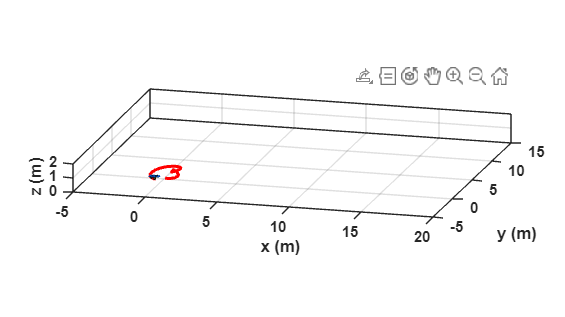

%% Inicialización
clear; clc; close all;

% Parámetros físicos del robot
r = 0.1;    % Radio de rueda [m]
l = 0.4;    % Distancia entre ruedas [m]
ts = 1;     % Tiempo de muestreo [s]

% Datos de entrada: tiempo, velocidades de las ruedas
t = 0:1:20;

wr = [4.582, 4.773, 5.291, 5.960, 6.490, ...
     -1.168, -1.364, 5.960, 5.291, 4.773, ...
      4.582, 4.773, 5.291, 5.960, 6.490, ...
      6.686, 6.490, 5.960, 5.291, 4.773, 4.582];

wl = [1.701, 2.353, 3.676, 4.856, 5.618, ...
     13.735, 13.472, 4.856, 3.676, 2.353, ...
      1.701, 2.353, 3.676, 4.856, 5.618, ...
      5.881, 5.618, 4.856, 3.676, 2.353, 1.701];

N = length(t);

%% Cálculo de velocidades u (lineal) y w (angular)
u = r * (wr + wl) / 2;
w = r * (wr - wl) / l;

%% Inicialización de estados
x = zeros(1, N+1);     % Posición en eje X
y = zeros(1, N+1);     % Posición en eje Y
theta = zeros(1, N+1); % Orientación en radianes

%% Integración usando el método de Euler
for k = 1:N
    theta(k+1) = theta(k) + w(k) * ts;
    x(k+1) = x(k) + u(k) * cos(theta(k)) * ts;
    y(k+1) = y(k) + u(k) * sin(theta(k)) * ts;
end

% Conversión de orientación a grados
theta_deg = rad2deg(theta);

%% Simulación 3D y animación
% Crear figura y configurar escena
scene = figure;
set(scene, 'Color', 'white');
set(gca, 'FontWeight', 'bold');
sizeScreen = get(0, 'ScreenSize');
set(scene, 'Position', sizeScreen);
camlight('headlight');
axis equal;
grid on;
box on;
xlabel('x (m)');
ylabel('y (m)');
zlabel('z (m)');
view([15 15]);
axis([-5 20 -5 15 0 2]);

% Escala de visualización del robot
scale = 4;

% Dibujo inicial del robot (requiere función externa MobilePlot_4)
% Asegúrate de tener la función MobilePlot_4.m en tu carpeta
H1 = MobilePlot_4(x(1), y(1), theta(1), scale); hold on;

% Trayectoria del punto de control
hx = x;
hy = y;
H2 = plot3(hx(1), hy(1), 0, 'c', 'LineWidth', 2);

% Animación
for k = 1:N
    delete(H1);
    delete(H2);

    H1 = MobilePlot_4(x(k), y(k), theta(k), scale);
    H2 = plot3(hx(1:k), hy(1:k), zeros(1, k), 'r', 'LineWidth', 2);

    pause(ts);
end

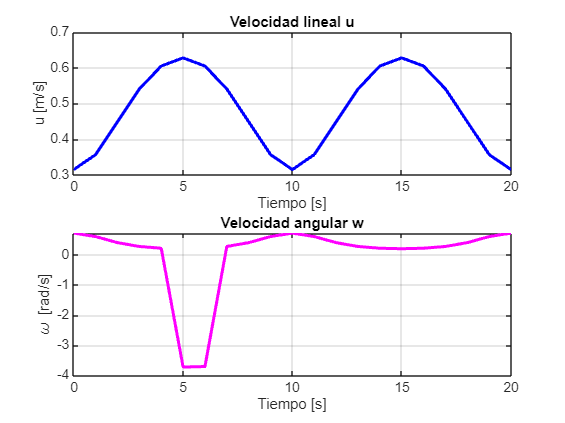


%% Gráficas finales

% Velocidades u y w
figure;
subplot(2,1,1)
plot(t, u, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('u [m/s]');
title('Velocidad lineal u');

subplot(2,1,2)
plot(t, w, 'm', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('\omega [rad/s]');
title('Velocidad angular w');

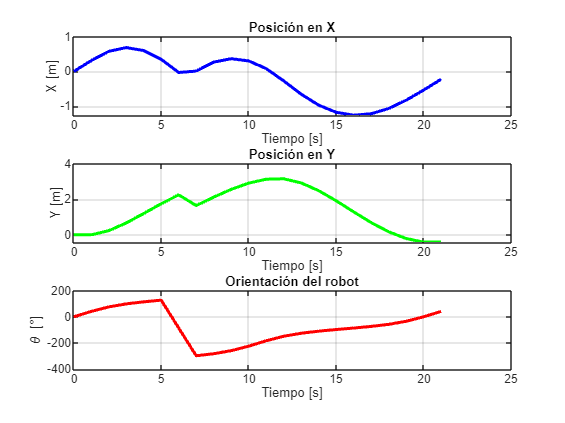


% Posición y orientación
figure;
subplot(3,1,1)
plot((0:N), x, 'b', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('X [m]');
title('Posición en X');

subplot(3,1,2)
plot((0:N), y, 'g', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('Y [m]');
title('Posición en Y');

subplot(3,1,3)
plot((0:N), theta_deg, 'r', 'LineWidth', 2); grid on;
xlabel('Tiempo [s]'); ylabel('\theta [°]');
title('Orientación del robot');

Mostrar resultados. 

%% Mostrar resultados en forma de tabla

% Recorta x, y y theta_deg para que tengan misma longitud que t
x_trim = x(1:end-1);
y_trim = y(1:end-1);
theta_trim = theta_deg(1:end-1);

% Crear tabla
T = table((0:N-1)', wr(:), wl(:), u(:), w(:), x_trim(:), y_trim(:), theta_trim(:), ...
    'VariableNames', {'t', 'wr', 'wl', 'u', 'w', 'x', 'y', 'theta_deg'});

% Mostrar tabla en consola
disp('Tabla de resultados de la simulación:');

Tabla de resultados de la simulación:


disp(T);

    t       wr        wl         u          w           x           y         theta_deg 
    __    ______    ______    _______    _______    _________    ________    ___________

     0     4.582     1.701    0.31415    0.72025            0           0              0
     1     4.773     2.353     0.3563      0.605      0.31415           0         41.267
     2     5.291     3.676    0.44835    0.40375      0.58196     0.23501         75.931
     3      5.96     4.856     0.5408      0.276      0.69095     0.66991         99.064
     4      6.49     5.618     0.6054      0.218      0.60575       1.204         114.88
     5    -1.168    13.735    0.62835    -3.7257      0.35106      1.7532         127.37
     6    -1.36